clear
load('01_Data/stepdata.Mat')
size(u)

ans =         1401           1


size(y)

ans =         1401           1


size(t)

ans =         1401           1


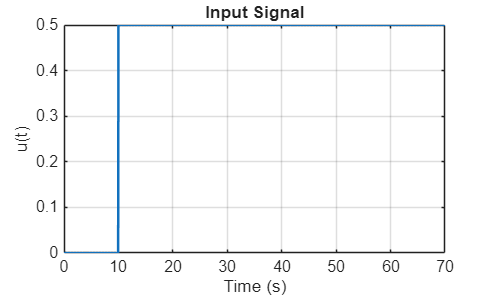


figure
plot(t,u, 'Linewidth',1.5)
xlabel('Time (s)');
ylabel('u(t)');
title('Input Signal');
grid on;

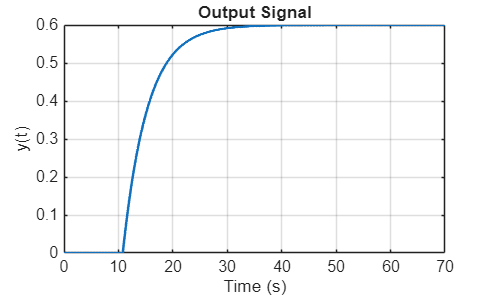


figure
plot(t,y,'linewidth',1.5)
xlabel('Time (s)');
ylabel('y(t)');
title('Output Signal');
grid on;

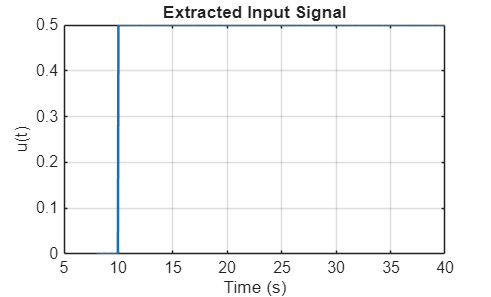


t_start = 8;
t_end = 40;
idx = (t >= t_start) & (t <= t_end);
t_step = t(idx);
u_step = u(idx);
y_step = y(idx);

figure
plot(t_step,u_step, 'Linewidth',1.5)
xlabel('Time (s)');
ylabel('u(t)');
title('Extracted Input Signal');
grid on;

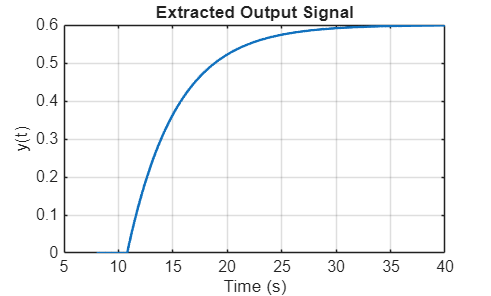


figure
plot(t_step,y_step,'linewidth',1.5)
xlabel('Time (s)');
ylabel('y(t)');
title('Extracted Output Signal');
grid on;

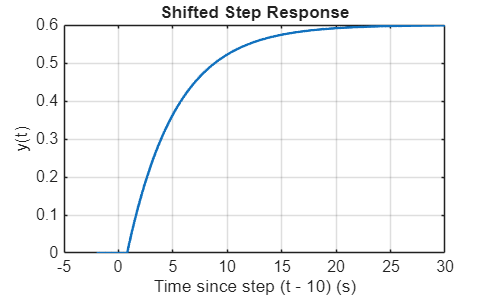


t0 = 10;                 % known step time
t_id = t_step - t0;

figure
plot(t_id,y_step,'linewidth',1.5)
grid on
xlabel('Time since step (t - 10) (s)')
ylabel('y(t)')
title('Shifted Step Response')


N = 20

N = 20


u_before = mean(u_step(1:N));
u_after = mean(u_step(end-N+1:end));
Delta_u = u_after - u_before

Delta_u = 0.5000


y_before = mean(y_step(1:N));
y_after = mean(y_step(end-N+1:end));
Delta_y = y_after - y_before

Delta_y = 0.5990


K_est = Delta_y / Delta_u

K_est = 1.1980


threshold = y_before + 0.02*Delta_y;
idx_L = find(y_step >= threshold, 1, 'first');
L_est = t_id(idx_L)

L_est = 0.9000


y_63 = y_before + 0.632*Delta_y;
idx_tau = find(y_step >= y_63, 1, 'first');
t_63 = t_id(idx_tau);
tau_est = t_63 - L_est

tau_est = 4.4000


fprintf('Estimated K   = %.4f\n', K_est);

Estimated K   = 1.1980


fprintf('Estimated L   = %.4f s\n', L_est);

Estimated L   = 0.9000 s


fprintf('Estimated tau = %.4f s\n', tau_est);

Estimated tau = 4.4000 s


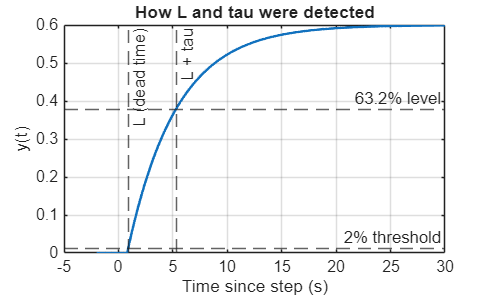


figure
plot(t_id, y_step, 'LineWidth', 1.5); grid on; hold on
yline(threshold, '--', '2% threshold')
yline(y_63, '--', '63.2% level')
xline(L_est, '--', 'L (dead time)')
xline(L_est + tau_est, '--', 'L + tau')
xlabel('Time since step (s)')
ylabel('y(t)')
title('How L and tau were detected')
hold off


G_ident = tf(K_est, [tau_est 1], 'InputDelay', L_est)


G_ident =
 
                  1.198
  exp(-0.9*s) * ---------
                4.4 s + 1
 
Continuous-time transfer function.



Delta_u

Delta_u = 0.5000

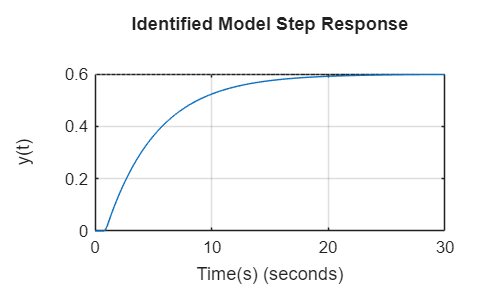


figure
step(Delta_u * G_ident)
grid on
title('Identified Model Step Response')
xlabel('Time(s)')
ylabel('y(t)')

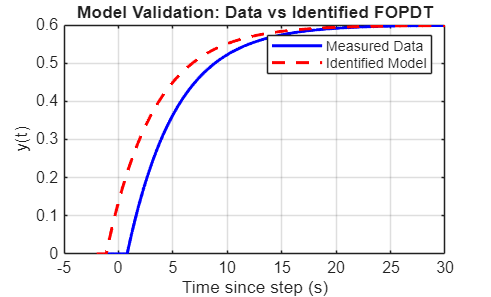


y_model = lsim(Delta_u * G_ident, ones(size(t_id)),t_id);

figure
plot(t_id, y_step, 'b', 'LineWidth', 1.8); hold on
plot(t_id, y_model, 'r--', 'LineWidth', 1.8)
grid on
xlabel('Time since step (s)')
ylabel('y(t)')
legend('Measured Data', 'Identified Model')
title('Model Validation: Data vs Identified FOPDT')
hold off


fit_error = norm(y_step - y_model) / norm(y_step) * 100;
fprintf('Relative fit error = %.2f %%\n', fit_error);

Relative fit error = 13.00 %
